% %[xDouble, fs] = audioread('AutoSample1.wav')
% 
 t = linspace(0, 4.8, 4.8E+4);
 f0 =   200;
 f1 = 10000;
% Fs = 1/mean(diff(t));
% x = chirp(t,f0,t(end),f1);
% sound(x, Fs)
% figure(1)
% plot(t, x)

%load handel.mat

%filename = 'handel.wav';
%audiowrite(filename,y,Fs);
%clear y Fs

Fs = 48000;

%[yDouble, Fs]

[yDouble, Fs] = audioread('HelloBetter.wav')

yDouble =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Fs = 48000

%n = linspace(0, 3*Fs, 3*Fs)

%y = sin(2*pi*500*n/Fs)
%y = chirp(t,f0,t(end),f1);
y = zeros(size(yDouble, 1), 1)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=1:size(y)
  y(i) = yDouble(i, 1);
end
x = y;%lowpass(y, 1000, Fs);
%.130899/2, Fs)
signalLength = size(x, 1)

signalLength = 61920

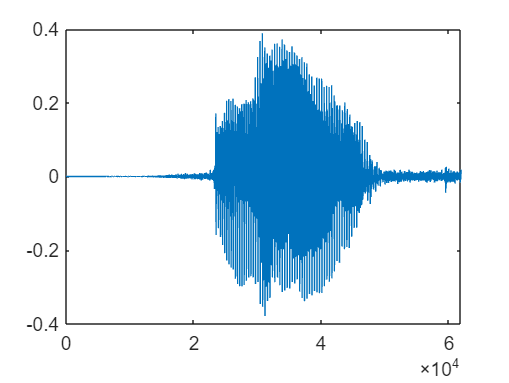

plot(x)

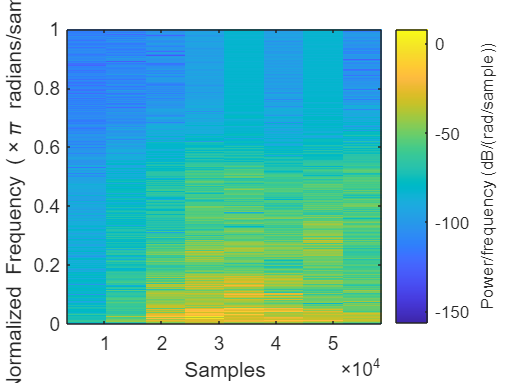

spectrogram(x, 'yaxis')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%signal generation
%signalLength = 100000
%x = MyChirpGenerator(100, 1000, Fs, signalLength)

%frequency in Hertz
%startingFreq = 100
%endingFreq = 1000
%Fs = 48000



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sound(x, Fs)
windowLength = 200;
startingCorellogramTime = 40000;
%begin the autocorrelation
delay = 0;
numDelaysToProcess = 500;
numCorellogramTimes = 2000;
z = zeros(numDelaysToProcess, numCorellogramTimes);%-windowLength+1, numDelaysToProcess)
%signalLength-windowLength+1, ...
xDelayed = zeros(size(x))

xDelayed =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for k=1:numDelaysToProcess
  for n=1:signalLength
    if (n-k<1)
      xDelayed(n) = 0;
    else
      xDelayed(n) = x(n-k);
    end
  end

  %now we can get the multiplied signal
  %xMultiplied = zeros(size(x));
  xMultiplied = x.*xDelayed*120;
  for m=1:numCorellogramTimes-1%size(x)-windowLength+1
    
    %if (m==1) 
    %  fprintf('hello')
    %end
    currSum = 0;
    for i=m+startingCorellogramTime:m+startingCorellogramTime+windowLength-1
      currSum = currSum+xMultiplied(i);
    end
    z(k, m) = currSum;
    %z(numDelaysToProcess - k + 1, m) = currSum;
  end
end
test = [1, 2, 3; 4, 5, 6]

test =      1     2     3
     4     5     6


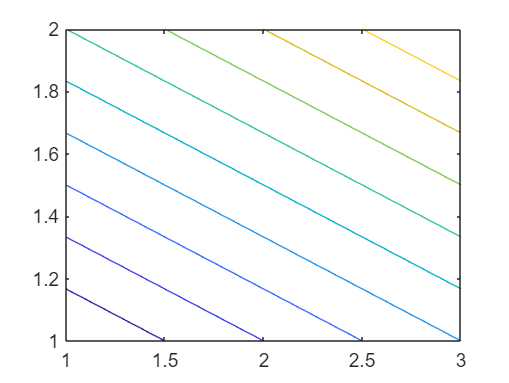

contour(test)

graphBound = max(z, [], 'all');%max(z)
%myZeros = zeros(1500, size(z, 2))
%z = cat(1, z, myZeros)
I = mat2gray(z,[-graphBound graphBound])

I =     0.9428    0.9426    0.9423    0.9421    0.9420    0.9418    0.9417    0.9416    0.9415    0.9414    0.9413    0.9412    0.9411    0.9411    0.9410    0.9410    0.9410    0.9409    0.9410    0.9410    0.9411    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9412    0.9413    0.9414    0.9415    0.9418    0.9421    0.9424    0.9429    0.9434    0.9440    0.9447    0.9456    0.9466    0.9478    0.9491    0.9505    0.9519    0.9534    0.9548
    0.9394    0.9392    0.9390    0.9388    0.9386    0.9384    0.9383    0.9382    0.9381    0.9380    0.9379    0.9378    0.9377    0.9376    0.9376    0.9375    0.9375    0.9375    0.9375    0.9375    0.9376    0.9376    0.9377    0.9377    0.9377    0.9377    0.9377    0.9377    0.9377    0.9376    0.9376    0.9376    0.9377    0.9377    0.9378    0.9380    0.9383    0.9386    0.9391    0.9396    0.9401    0.9408    0.9416    0.9425    0.9436    0.9448    0.9461    0.9475    0.9490    0

%I = transpose(I)
z(1, 1)

ans = 498.0551

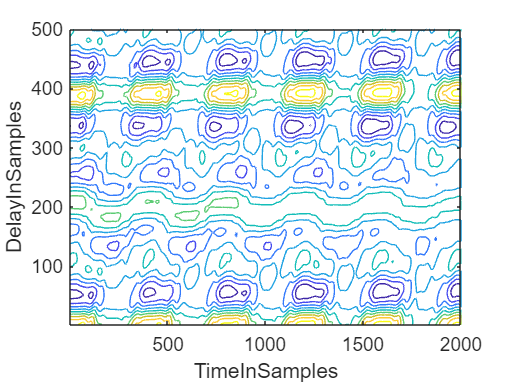

contour(z)
xlabel('TimeInSamples')
ylabel('DelayInSamples')

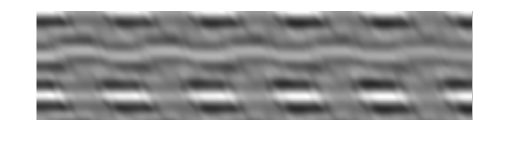


%plot(I)


%figure
imshow(I)

%h = heatmap(z)
%[acf,lags] = autocorr(y)

%plot(t,y); xlabel('Seconds'); ylabel('Amplitude');
%    figure
 %   plot(psd(spectrum.periodogram,y,'Fs',fs,'NFFT',length(y)));